# Task 3)

### Part 1. Recreating the system from Task 2:

clear
syms a1 a2 a3 a4
syms s11 s21 s31 s41 s12 s22 s32 s42 s13 s23 s33 s43 s14 s24 s34 s44
A=[0 1 0 0; 42.51 0 0 0; 0 0 0 1; -2.943 0 0 0]

A =          0    1.0000         0         0
   42.5100         0         0         0
         0         0         0    1.0000
   -2.9430         0         0         0


B=[0 -3.333 0 1]'

B =          0
   -3.3330
         0
    1.0000


C=[1 0 0 0;0 0 1 0]

C =      1     0     0     0
     0     0     1     0


Contr=[B A*B (A^2)*B (A^3)*B]

Contr =          0   -3.3330         0 -141.6858
   -3.3330         0 -141.6858         0
         0    1.0000         0    9.8090
    1.0000         0    9.8090         0


a=[a1 a2 a3 a4]

$$a = \left(\begin{array}{cccc} a_{1} & a_{2} & a_{3} & a_{4} \end{array}\right)$$

Ac=[a;1 0 0 0;0 1 0 0;0 0 1 0]

$$Ac = \left(\begin{array}{cccc} a_{1} & a_{2} & a_{3} & a_{4}\\ 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0 \end{array}\right)$$

Bc=[1 0 0 0]'

Bc =      1
     0
     0
     0


Cc=[Bc Ac*Bc (Ac^2)*Bc (Ac^3)*Bc]

$$Cc = \left(\begin{array}{cccc} 1 & a_{1} & {a_{1}}^{2}+a_{2} & a_{3}+a_{1}\,a_{2}+a_{1}\,\left({a_{1}}^{2}+a_{2}\right)\\ 0 & 1 & a_{1} & {a_{1}}^{2}+a_{2}\\ 0 & 0 & 1 & a_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

det(Cc)

$$ans = 1$$

T1=[s11 s21 s31 s41;s12 s22 s32 s42;s13 s23 s33 s43;s14 s24 s34 s44]

$$T1 = \left(\begin{array}{cccc} s_{11} & s_{21} & s_{31} & s_{41}\\ s_{12} & s_{22} & s_{32} & s_{42}\\ s_{13} & s_{23} & s_{33} & s_{43}\\ s_{14} & s_{24} & s_{34} & s_{44} \end{array}\right)$$

s4=[s14 s24 s34 s44]

$$s4 = \left(\begin{array}{cccc} s_{14} & s_{24} & s_{34} & s_{44} \end{array}\right)$$

s3=[s13 s23 s33 s43]

$$s3 = \left(\begin{array}{cccc} s_{13} & s_{23} & s_{33} & s_{43} \end{array}\right)$$

s2=[s12 s22 s32 s42]

$$s2 = \left(\begin{array}{cccc} s_{12} & s_{22} & s_{32} & s_{42} \end{array}\right)$$

s1=[s11 s21 s31 s41]

$$s1 = \left(\begin{array}{cccc} s_{11} & s_{21} & s_{31} & s_{41} \end{array}\right)$$

s4==[0 0 0 1]/(Contr)

$$ans = \left(\begin{array}{cccc} s_{14}=-\frac{5289001001014353}{576460752303423488} & s_{24}=0 & s_{34}=-\frac{8814120168190419}{288230376151711744} & s_{44}=0 \end{array}\right)$$

w = vpa(ans)

$$w = \left(\begin{array}{cccc} s_{14}=-0.0091749542009244306611792652006443 & s_{24}=0.0 & s_{34}=-0.03058012235168112644134730260248 & s_{44}=0.0 \end{array}\right)$$

s3==s4*A

$$ans = \left(\begin{array}{cccc} s_{13}=\frac{4251\,s_{24}}{100}-\frac{2943\,s_{44}}{1000} & s_{23}=s_{14} & s_{33}=0 & s_{43}=s_{34} \end{array}\right)$$

var = vpa(ans)

$$var = \left(\begin{array}{cccc} s_{13}=42.51\,s_{24}-2.943\,s_{44} & s_{23}=s_{14} & s_{33}=0.0 & s_{43}=s_{34} \end{array}\right)$$

s2==s3*A

$$ans = \left(\begin{array}{cccc} s_{12}=\frac{4251\,s_{23}}{100}-\frac{2943\,s_{43}}{1000} & s_{22}=s_{13} & s_{32}=0 & s_{42}=s_{33} \end{array}\right)$$

% s14 = -0.0092; s24= 0; s34 = -0.0306;s44=0;
% s13 = 0 ; s23 =s14; s33= 0; s43=s34;
var2 = subs(ans,[s14,s24,s34,s44,s13,s23,s33,s43],...
    [-0.0092,0,-0.0306,0,0,-0.0092,0,-0.0306])

$$var2 = \left(\begin{array}{cccc} s_{12}=-\frac{1505181}{5000000} & s_{22}=0 & s_{32}=0 & s_{42}=0 \end{array}\right)$$


var = vpa(var2)

$$var = \left(\begin{array}{cccc} s_{12}=-0.3010362 & s_{22}=0.0 & s_{32}=0.0 & s_{42}=0.0 \end{array}\right)$$

s1==s2*A

$$ans = \left(\begin{array}{cccc} s_{11}=\frac{4251\,s_{22}}{100}-\frac{2943\,s_{42}}{1000} & s_{21}=s_{12} & s_{31}=0 & s_{41}=s_{32} \end{array}\right)$$

var3 = subs(ans,[s12,s22,s32,s42],[-0.3 0 0 0])

$$var3 = \left(\begin{array}{cccc} s_{11}=0 & s_{21}=-\frac{3}{10} & s_{31}=0 & s_{41}=0 \end{array}\right)$$

var4 = vpa(var3)

$$var4 = \left(\begin{array}{cccc} s_{11}=0.0 & s_{21}=-0.3 & s_{31}=0.0 & s_{41}=0.0 \end{array}\right)$$

T1=[s11 s21 s31 s41;s12 s22 s32 s42;...
    s13 s23 s33 s43;s14 s24 s34 s44]

$$T1 = \left(\begin{array}{cccc} s_{11} & s_{21} & s_{31} & s_{41}\\ s_{12} & s_{22} & s_{32} & s_{42}\\ s_{13} & s_{23} & s_{33} & s_{43}\\ s_{14} & s_{24} & s_{34} & s_{44} \end{array}\right)$$

T1ac = subs(T1,[s14,s24,s34,s44,...
    s13,s23,s33,s43,s12,s22,s32,s42,...
    s11,s21,s31,s41],[-0.0092,0,-0.0306,...
    0,0,-0.0092,0,-0.0306,-0.3,0,0,...
    0,0,-0.3,0,0])

$$T1ac = \left(\begin{array}{cccc} 0 & -\frac{3}{10} & 0 & 0\\ -\frac{3}{10} & 0 & 0 & 0\\ 0 & -\frac{23}{2500} & 0 & -\frac{153}{5000}\\ -\frac{23}{2500} & 0 & -\frac{153}{5000} & 0 \end{array}\right)$$

ans=vpa(inv(T1ac));
disp(ans(:,1:2))

$$\left(\begin{array}{cc} 0 & -3.3333333333333333333333333333333\\ -3.3333333333333333333333333333333 & 0\\ 0 & 1.0021786492374727668845315904139\\ 1.0021786492374727668845315904139 & 0 \end{array}\right)$$

disp(ans(:,3:4))

$$\left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & -32.67973856209150326797385620915\\ -32.67973856209150326797385620915 & 0 \end{array}\right)$$


Ac=T1ac*A*inv(T1ac)

$$Ac = \left(\begin{array}{cccc} 0 & \frac{4251}{100} & 0 & 0\\ 1 & 0 & 0 & 0\\ 0 & \frac{501727}{500000} & 0 & 0\\ 0 & 0 & 1 & 0 \end{array}\right)$$


Bc=vpa(T1ac*B)

$$Bc = \left(\begin{array}{c} 0.9999\\ 0\\ 0.0000636\\ 0 \end{array}\right)$$

Bc=[1 0 0 0]'

Bc =      1
     0
     0
     0


Cc=([Bc Ac*Bc (Ac^2)*Bc (Ac^3)*Bc])

$$Cc = \left(\begin{array}{cccc} 1 & 0 & \frac{4251}{100} & 0\\ 0 & 1 & 0 & \frac{4251}{100}\\ 0 & 0 & \frac{501727}{500000} & 0\\ 0 & 0 & 0 & \frac{501727}{500000} \end{array}\right)$$

Cc=C*inv(T1ac)

$$Cc = \left(\begin{array}{cccc} 0 & -\frac{10}{3} & 0 & 0\\ 0 & \frac{460}{459} & 0 & -\frac{5000}{153} \end{array}\right)$$

vpa(Cc)

$$ans = \left(\begin{array}{cccc} 0 & -3.3333333333333333333333333333333 & 0 & 0\\ 0 & 1.0021786492374727668845315904139 & 0 & -32.67973856209150326797385620915 \end{array}\right)$$

Dc=[0;0]

Dc =      0
     0


syms lamb f1 f2 f3 f4

Fc=[f1 f2 f3 f4]

$$Fc = \left(\begin{array}{cccc} f_{1} & f_{2} & f_{3} & f_{4} \end{array}\right)$$

id=eye(4);
l_m=id*lamb

$$l\_m = \left(\begin{array}{cccc} \mathrm{lamb} & 0 & 0 & 0\\ 0 & \mathrm{lamb} & 0 & 0\\ 0 & 0 & \mathrm{lamb} & 0\\ 0 & 0 & 0 & \mathrm{lamb} \end{array}\right)$$

P=det(l_m-Ac)

$$P = \frac{{\mathrm{lamb}}^{2}\,\left(100\,{\mathrm{lamb}}^{2}-4251\right)}{100}$$

simplify(P)

$$ans = {\mathrm{lamb}}^{4}-\frac{4251\,{\mathrm{lamb}}^{2}}{100}$$

a1=0;a2=-42.51;a3=0;a4=0;
acl1=13.52;acl2=56.64;acl3=76.72;acl4=32.6;
Fc=[a1-acl1 a2-acl2 a3-acl3 a4-acl4]

Fc =   -13.5200  -99.1500  -76.7200  -32.6000


F=Fc*T1ac

$$F = \left(\begin{array}{cccc} \frac{751123}{25000} & \frac{148807}{31250} & \frac{24939}{25000} & \frac{146727}{62500} \end{array}\right)$$

vpa(F)

$$ans = \left(\begin{array}{cccc} 30.04492 & 4.761824 & 0.99756 & 2.347632 \end{array}\right)$$

round(vpa(eig(A+B*F)),4)

$$ans = \left(\begin{array}{c} -6.5541\\ -4.9652\\ -1.0448\\ -0.9594 \end{array}\right)$$

round(vpa(eig(Ac+Bc*Fc)),4)

$$ans = \left(\begin{array}{c} -6.5539\\ -4.951\\ -1.0912\\ -0.9239 \end{array}\right)$$

### Part. 2: Based on the results of the task 2 shown above we will create a closed-loop state feedback system.

Asf = A+B*F %calculating state feedback matrix A

$$Asf = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ -\frac{1440742959}{25000000} & -\frac{495973731}{31250000} & -\frac{83121687}{25000000} & -\frac{489041091}{62500000}\\ 0 & 0 & 0 & 1\\ \frac{169387}{6250} & \frac{148807}{31250} & \frac{24939}{25000} & \frac{146727}{62500} \end{array}\right)$$

vpa(Asf) %numerical approximation of the results

$$ans = \left(\begin{array}{cccc} 0 & 1.0 & 0 & 0\\ -57.62971836 & -15.871159392 & -3.32486748 & -7.824657456\\ 0 & 0 & 0 & 1.0\\ 27.10192 & 4.761824 & 0.99756 & 2.347632 \end{array}\right)$$

%changing from symbolic to numerical
Asf=[0 1 0 0;-57.6297 -15.8712 -3.3249 -7.8247;...
    0 0 0 1;27.1019 4.7618 0.9976 2.3476] 

Asf =          0    1.0000         0         0
  -57.6297  -15.8712   -3.3249   -7.8247
         0         0         0    1.0000
   27.1019    4.7618    0.9976    2.3476


Bsf = B %calculating state feedback matrix B

Bsf =          0
   -3.3330
         0
    1.0000


Csf = C %calculating state feedback matrix C

Csf =      1     0     0     0
     0     0     1     0


Dsf = Dc %calculating state feedback matrix D

Dsf =      0
     0


%printing transfer functions of the system (for both outputs)
[numf1, denf1] = ss2tf(Asf, Bsf, Csf(1,:), Dsf(1,:));
Gf1 = tf(numf1, denf1)

Gf1 =
 
      -3.333 s^2 - 0.0001492 s + 0.0001008
  ---------------------------------------------
  s^4 + 13.52 s^3 + 56.63 s^2 + 76.77 s + 32.62
 
Continuous-time transfer function.



[numf2, denf2] = ss2tf(Asf, Bsf, Csf(2,:), Dsf(2,:));
Gf2 = tf(numf2, denf2)

Gf2 =
 
            s^2 + 0.0001206 s - 32.7
  ---------------------------------------------
  s^4 + 13.52 s^3 + 56.63 s^2 + 76.77 s + 32.62
 
Continuous-time transfer function.



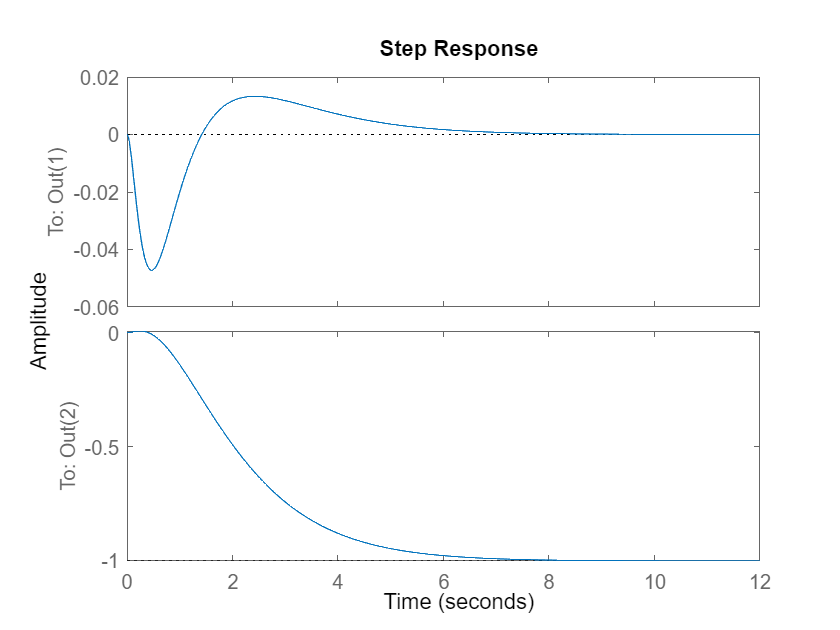

sys=ss(Asf,Bsf,Csf,Dsf); %creating state feedback system
step(sys) %plotting step of the state feedback system

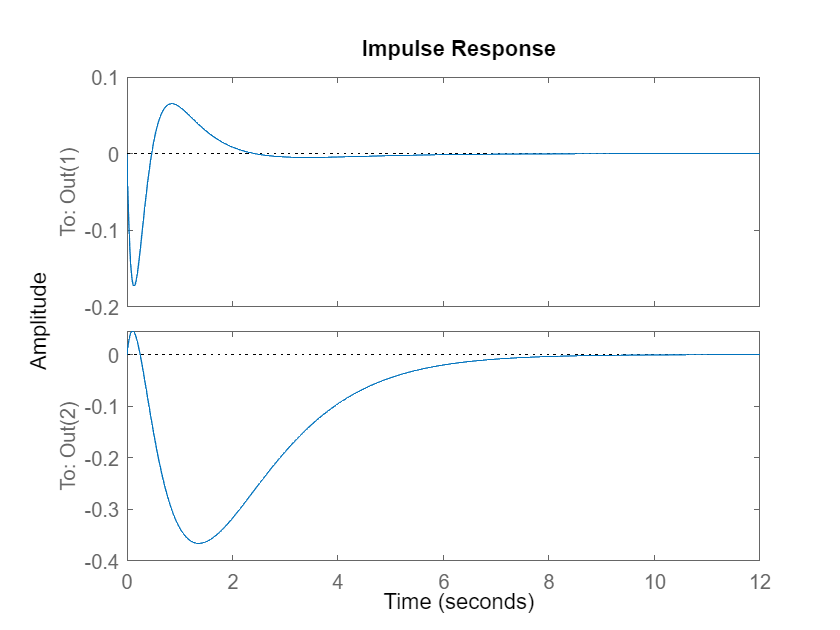

impulse(sys) %plotting impulse of the state feedback system

#### Conclusions:

    The state feedback controler we have created allows us to place 4 poles in the desired locations {-1 -1 -5 -6.52}.

It is proven by the transfer functions of the closed-loop state feedback system shown above, as well as the eigenvalues 

displayed at the end of previous section of code.

    From the impulse and step plots we can deduce that the system is working correctly under the influence of the compensator.

It is proven by both plots reaching amplitude of 0 which corresponds to the stable, vertical position. Additionally both systems are stable.

    Depending on the type of the input the input the system will take different time to reach its stable position. In the case of pendulum the step 

response settling time is equal to t=6.73s and for inpulse it is equal t=4.50s. While the cart requires t=6.18s and t=7.2s respectively to stop its movement.

# Task 5)

### Part 1: compute the closed-loop state observer

syms a1 a2 a3 a4
Ao=[a1 1 0 0;a2 0 1 0;a3 0 0 1; a4 0 0 0]

$$Ao = \left(\begin{array}{cccc} a_{1} & 1 & 0 & 0\\ a_{2} & 0 & 1 & 0\\ a_{3} & 0 & 0 & 1\\ a_{4} & 0 & 0 & 0 \end{array}\right)$$

Co=[1 0 0 0]

Co =      1     0     0     0


Ooa=[C(2,:);(C(2,:)*A);(C(2,:)*A^2);(C(2,:)*A^3)]

Ooa =          0         0    1.0000         0
         0         0         0    1.0000
   -2.9430         0         0         0
         0   -2.9430         0         0


Oo=[Co;(Co*Ao);(Co*Ao^2);(Co*Ao^3)]

$$Oo = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ a_{1} & 1 & 0 & 0\\ {a_{1}}^{2}+a_{2} & a_{1} & 1 & 0\\ a_{3}+a_{1}\,a_{2}+a_{1}\,\left({a_{1}}^{2}+a_{2}\right) & {a_{1}}^{2}+a_{2} & a_{1} & 1 \end{array}\right)$$

det(Oo)

$$ans = 1$$

syms t4

eq1=t4==inv(Ooa)*[0;0;0;1]

$$eq1 = \left(\begin{array}{c} t_{4}=0\\ t_{4}=-\frac{1000}{2943}\\ t_{4}=0\\ t_{4}=0 \end{array}\right)$$

vpa(eq1)

$$ans = \left(\begin{array}{c} t_{4}=0.0\\ t_{4}=-0.33978933061501868841318382602786\\ t_{4}=0.0\\ t_{4}=0.0 \end{array}\right)$$

t4=[0 -0.3398 0 0]'

t4 =          0
   -0.3398
         0
         0


t3=A*t4

t3 =    -0.3398
         0
         0
         0


t2=A*t3

t2 =          0
  -14.4449
         0
    1.0000


t1=A*t2

t1 =   -14.4449
         0
    1.0000
         0


S=[t1 t2 t3 t4]

S =   -14.4449         0   -0.3398         0
         0  -14.4449         0   -0.3398
    1.0000         0         0         0
         0    1.0000         0         0


Ao=inv(S)*A*S

Ao =          0    1.0000         0         0
   42.5100         0    1.0000         0
         0         0         0    1.0000
         0         0         0         0


Bo=inv(S)*B

Bo =          0
    1.0000
         0
  -32.7000


Co=C*S

Co =   -14.4449         0   -0.3398         0
    1.0000         0         0         0


Do=[0;0];
syso=ss(Ao,Bo,Co,Do);
round(vpa(eig(A)),4)

$$ans = \left(\begin{array}{c} 0\\ 0\\ 6.52\\ -6.52 \end{array}\right)$$

round(vpa(eig(Ac)),4)

$$ans = \left(\begin{array}{c} 0\\ 0\\ -6.52\\ 6.52 \end{array}\right)$$

round(vpa(eig(Ao)),4)

$$ans = \left(\begin{array}{c} 6.52\\ -6.52\\ 0\\ 0 \end{array}\right)$$

syms lamb
det(lamb*eye(4)-Ao)

$$ans = \frac{{\mathrm{lamb}}^{2}\,\left(100\,{\mathrm{lamb}}^{2}-4251\right)}{100}$$

expand(ans)

$$ans = {\mathrm{lamb}}^{4}-\frac{4251\,{\mathrm{lamb}}^{2}}{100}$$

a1=0;a2=-42.51;a3=0;a4=0;
acl1=135.2;acl2=5664;acl3=76720;acl4=326000;
Lo=[a1-acl1 a2-acl2 a3-acl3 a4-acl4]'

Lo = 1.0e+05 *

   -0.0014
   -0.0571
   -0.7672
   -3.2600


L=S*Lo

L = 1.0e+05 *

    0.2802
    1.9320
   -0.0014
   -0.0571


eig(A+L*C(2,:))

ans =   -65.2121
  -49.9921
  -10.0091
   -9.9910


eig(Ao+Lo*Co(2,:))

ans =   -65.2121
  -49.9921
  -10.0091
   -9.9910


#### Part 2: Computing prepared state observer and calculating eigenvalues

Aso = A+L*C(2,:); Bso = B; Cso = C; Dso = Do;
sysso=ss(Aso,Bso,Cso,Dso)

sysso =
 
  A = 
              x1         x2         x3         x4
   x1          0          1  2.802e+04          0
   x2      42.51          0  1.932e+05          0
   x3          0          0     -135.2          1
   x4     -2.943          0      -5707          0
 
  B = 
           u1
   x1       0
   x2  -3.333
   x3       0
   x4       1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



eig(Aso)

ans =   -65.2121
  -49.9921
  -10.0091
   -9.9910


# Task 6) 

#### Part 1: Recomputing Asf

Asf=A+B*F

$$Asf = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ -\frac{1440742959}{25000000} & -\frac{495973731}{31250000} & -\frac{83121687}{25000000} & -\frac{489041091}{62500000}\\ 0 & 0 & 0 & 1\\ \frac{169387}{6250} & \frac{148807}{31250} & \frac{24939}{25000} & \frac{146727}{62500} \end{array}\right)$$

vpa(Asf)

$$ans = \left(\begin{array}{cccc} 0 & 1.0 & 0 & 0\\ -57.62971836 & -15.871159392 & -3.32486748 & -7.824657456\\ 0 & 0 & 0 & 1.0\\ 27.10192 & 4.761824 & 0.99756 & 2.347632 \end{array}\right)$$

Asf=[0 1 0 0;-57.6297 -15.871 -3.3248 -7.824657;0 0 0 1;27.10192 4.7618 1 2.3476]

Asf =          0    1.0000         0         0
  -57.6297  -15.8710   -3.3248   -7.8247
         0         0         0    1.0000
   27.1019    4.7618    1.0000    2.3476


Bsf=B;
Csf=C;
Dsf=Do;

### Part 2: Computing observer base state feedback system

Areg = [ (A+B*F) B*F; zeros(size(A)) (A+L*C(2,:)) ];
Areg(:,1:4)

$$ans = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ -\frac{1440742959}{25000000} & -\frac{495973731}{31250000} & -\frac{83121687}{25000000} & -\frac{489041091}{62500000}\\ 0 & 0 & 0 & 1\\ \frac{169387}{6250} & \frac{148807}{31250} & \frac{24939}{25000} & \frac{146727}{62500}\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

Areg(:,5:8)

$$ans = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ -\frac{2503492959}{25000000} & -\frac{495973731}{31250000} & -\frac{83121687}{25000000} & -\frac{489041091}{62500000}\\ 0 & 0 & 0 & 0\\ \frac{751123}{25000} & \frac{148807}{31250} & \frac{24939}{25000} & \frac{146727}{62500}\\ 0 & 1 & \frac{1925685091607349}{68719476736} & 0\\ \frac{4251}{100} & 0 & \frac{3319232414667921}{17179869184} & 0\\ 0 & 0 & -\frac{4757076473921227}{35184372088832} & 1\\ -\frac{2943}{1000} & 0 & -\frac{6274571114366731}{1099511627776} & 0 \end{array}\right)$$

vpa(Areg(:,1:4))

$$ans = \left(\begin{array}{cccc} 0 & 1.0 & 0 & 0\\ -57.62971836 & -15.871159392 & -3.32486748 & -7.824657456\\ 0 & 0 & 0 & 1.0\\ 27.10192 & 4.761824 & 0.99756 & 2.347632\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

vpa(Areg(:,5:8))

$$ans = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ -100.13971836 & -15.871159392 & -3.32486748 & -7.824657456\\ 0 & 0 & 0 & 0\\ 30.04492 & 4.761824 & 0.99756 & 2.347632\\ 0 & 1.0 & 28022.406209599997964687645435333 & 0\\ 42.51 & 0 & 193204.75488597998628392815589905 & 0\\ 0 & 0 & -135.20424527999998076666088309139 & 1.0\\ -2.943 & 0 & -5706.689184414000010292511433363 & 0 \end{array}\right)$$

Areg=[0 1 0 0 0 0 0 0;-57.6297 -15.871 -3.3248 -7.8246 -100.139 -15.871 -3.3248 -7.8246;...
    0 0 0 1 0 0 0 0;27.101 4.7618 1 2.347 30.044 4.7618 1 2.347;...
    0 0 0 0 0 1 28022.406 0;0 0 0 0 42.51 0 193204.7548 0;...
    0 0 0 0 0 0 -135.204 1;0 0 0 0 -2.943 0 -5706.69 0]

Areg = 1.0e+05 *

         0    0.0000         0         0         0         0         0         0
   -0.0006   -0.0002   -0.0000   -0.0001   -0.0010   -0.0002   -0.0000   -0.0001
         0         0         0    0.0000         0         0         0         0
    0.0003    0.0000    0.0000    0.0000    0.0003    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0000    0.2802         0
         0         0         0         0    0.0004         0    1.9320         0
         0         0         0         0         0         0   -0.0014    0.0000
         0         0         0         0   -0.0000         0   -0.0571         0


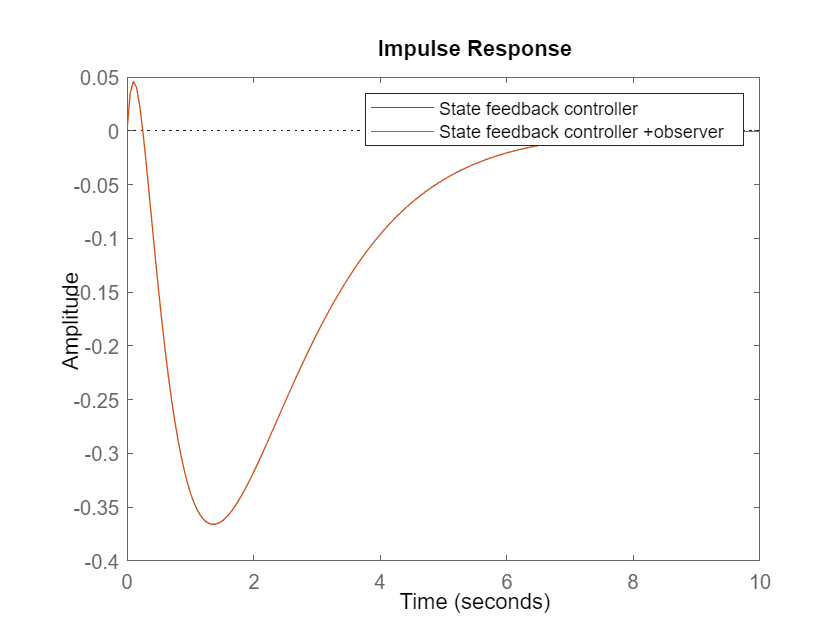

Breg = [ B; zeros(size(B)) ];
Creg = [ C(2,:) zeros(size(C(2,:))) ];
Dreg = 0;
sys_sf=ss(Asf,Bsf,Csf(2,:),Dsf(2,:));
sys_reg=ss(Areg,Breg,Creg,Dreg);
figure
impulse(sys_sf);hold on
impulse(sys_reg);hold off
legend('State feedback controller','State feedback controller +observer');
xlim([0 10]);

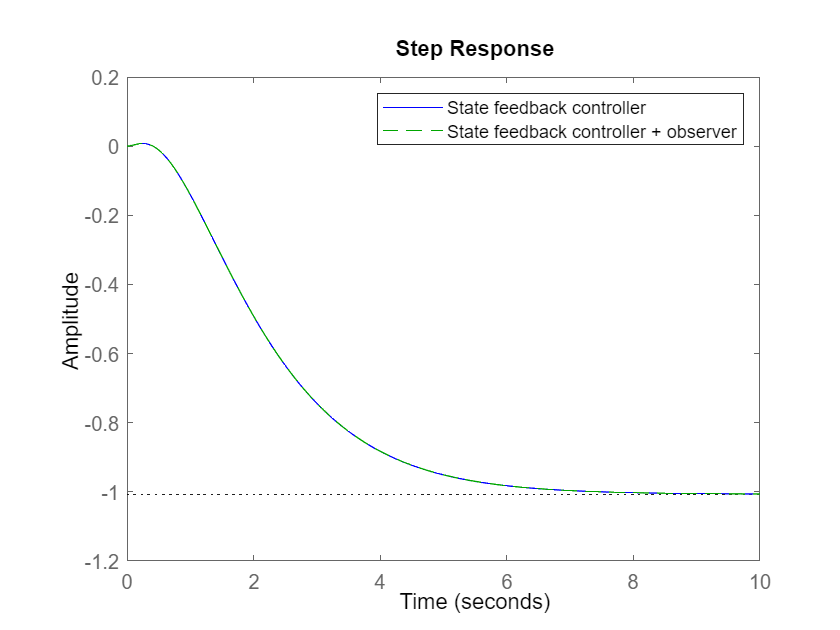

figure
step(sys_sf,'b');
hold on
step(sys_reg,'g--');
legend('State feedback controller','State feedback controller + observer');
xlim([0 10]);   

#### Conclusions:

    From the Step and Implse responses presented above we can observe that the results obtained using both methods were basically identical.

The result was expected since both methods allow us to create apropriate controllers, and for such a simple system the results would obviously be similar.

    The main difference between the two approaches lies in the information they require and the complexity of implementation state feedback control relies on

direct state measurements, while observer-based state feedback control uses an observer to estimate the unmeasured states.Observer-based control offers

more flexibility in dealing with partially measurable systems but introduces additional complexity in the design and implementation process.

# Task 7)

A = [0, 1, 0, 0; 42.51, 0, 0, 0; 0, 0, 0, 1; -(2.943), 0, 0, 0];
B = [0; -(3.333); 0; 1];
C = [1, 0, 0, 0; 0, 0, 1, 0];
D = [0; 0];
system_order = length(A)

system_order = 4

M = ctrb(A,B);
rank(M)

ans = 4

N = obsv(A,C);
rank(N)

ans = 4

desiredPoles = [-1 -1 -5 -6.52];
K = acker(A,B,desiredPoles)

K =   -30.0471   -4.7603   -0.9969   -2.3461


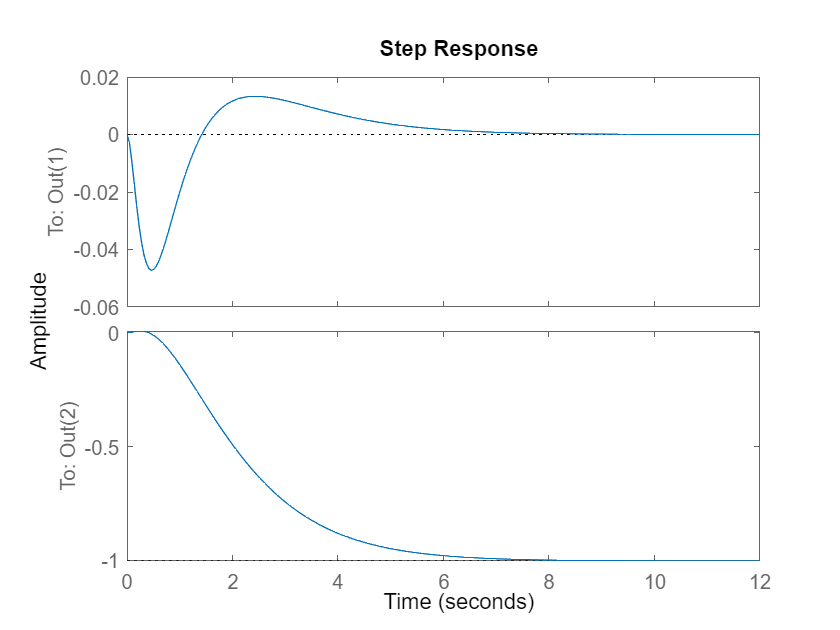

% K = place(A,B,desiredPoles);
% closed-loop system
Ac = A-B*K; Bc = B; Cc = C; Dc = D;
sys_closed = ss(Ac,Bc,Cc,Dc);
tf_closed = tf(sys_closed);
figure
step(sys_closed);

stepinfo(sys_closed)

ans = 2×1 struct array with fields:
    RiseTime
    TransientTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


eig(sys_closed)

ans =   -6.5200 + 0.0000i
  -5.0000 + 0.0000i
  -1.0000 + 0.0000i
  -1.0000 - 0.0000i


observerPoles = 10 * desiredPoles;
L = acker(A',C(2,:)',observerPoles)

L = 1.0e+05 *

   -0.2802   -1.9320    0.0014    0.0571


% L = place(A',C(2,:)',observerPoles);

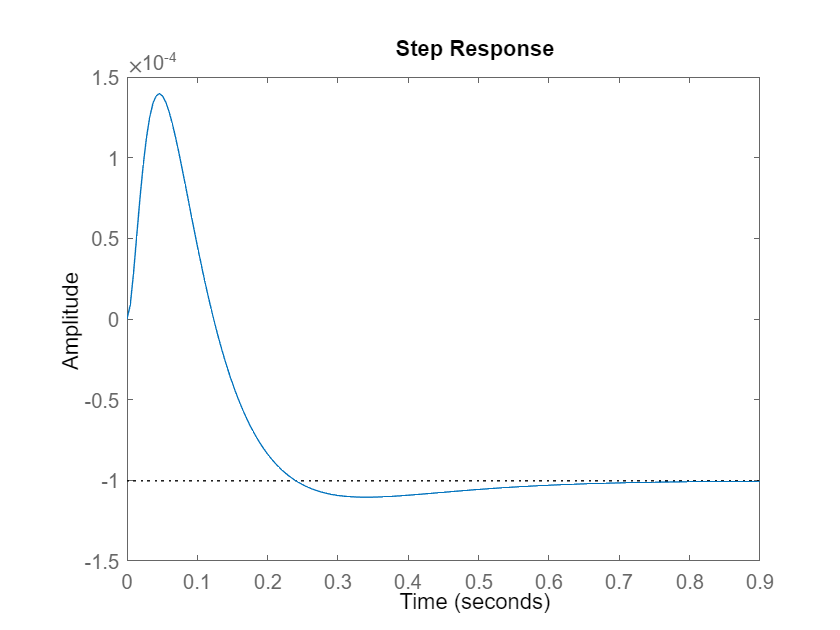

Ao = A - L'*C(2,:); Bo = B; Co = C(2,:); Do = D(2,:);
sys_observer = ss(Ao,Bo,Co,Do);
tf_observer = tf(sys_observer);
figure
step(sys_observer);

stepinfo(sys_observer)

ans = struct with fields:
         RiseTime: 0.0835
    TransientTime: 0.5168
     SettlingTime: 0.6412
      SettlingMin: -1.1045e-04
      SettlingMax: -9.2001e-05
        Overshoot: 10.1105
       Undershoot: 139.2860
             Peak: 1.3972e-04
         PeakTime: 0.0461


eig(sys_observer)

ans =  -65.2000 + 0.0000i
 -50.0000 + 0.0000i
 -10.0000 + 0.0000i
 -10.0000 - 0.0000i


Areg = [(A-B*K) B*K;zeros(size(A)) (A+L'*C(2,:))];
Breg = [B; zeros(size(B))];
Creg = [C zeros(size(C))];
Dreg = 0;

sys_reg = ss(Areg,Breg,Creg,Dreg);
tf_reg = tf(sys_reg);
result_eig = eig(sys_reg)

result_eig = 1.0e+02 *

  -0.0652 + 0.0000i
  -0.0500 + 0.0000i
  -0.0100 + 0.0000i
  -0.0100 - 0.0000i
   1.7141 + 0.0000i
  -0.1381 + 0.0553i
  -0.1381 - 0.0553i
  -0.0859 + 0.0000i


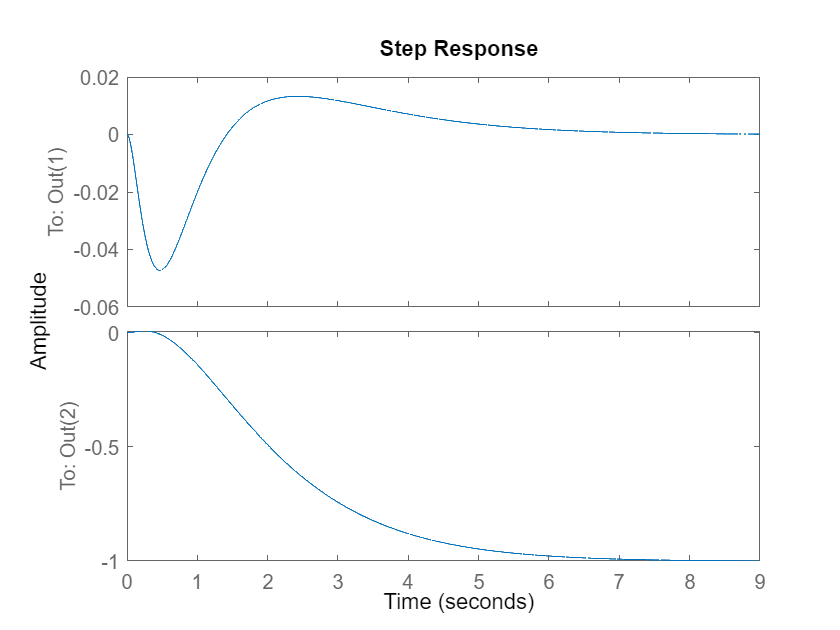

figure
step(sys_reg);

stepinfo(sys_reg)

ans = 2×1 struct array with fields:
    RiseTime
    TransientTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


#### Conclusions:

    Matlab functions like Acker or Place ensure good stability, performance and ease of use due to being optimized for Matlab. Both require that the state-space matrices A and B are controllable.

     While Acker is better suited for lower order systems (up to 4th) and is capable of placing two poles at the same location, Place function performs better for higher order systems. In this case the place function shows its limitations by not being able to place two poles at the same location. Acker is not numerically reliable and starts to break down rapidly for problems of greater order. It is also only applicable for SISO systems while place command works for MIMO systems too.